Example of a spectrogram, which in this case produces an autospectrum over 1.5 hours every 3 hours.

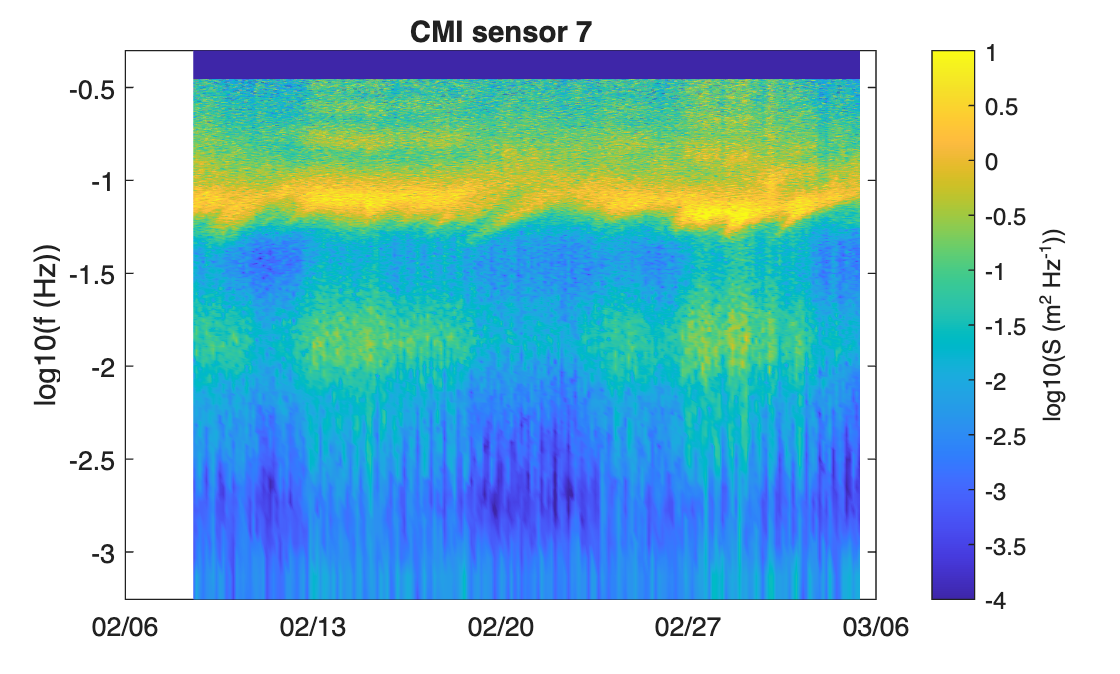

load CMI_data.mat
x = detrend(CMI.e7);
t = CMI.t;
[m,n] = size(x);
navg = 5;
r_win = .1;
tm = mean(t);

[S,Su,Sl,f] = auto_spc(x(:,1),1,navg,r_win);
Nf = length(f);
Sout = NaN(Nf,n);
for j = 1:n
    [S,Su,Sl,f] = auto_spc(x(:,j),1,navg,r_win);
    Sout(:,j) = S;
end

figure (1)
pcolor(tm,log10(f),log10(Sout));
shading interp
ylabel('log10(f (Hz))')
cb = colorbar;
ylabel(cb,'log10(S (m^2 Hz^{-1}))')
caxis([-4 1])
datetick('x')
title('CMI sensor 7')

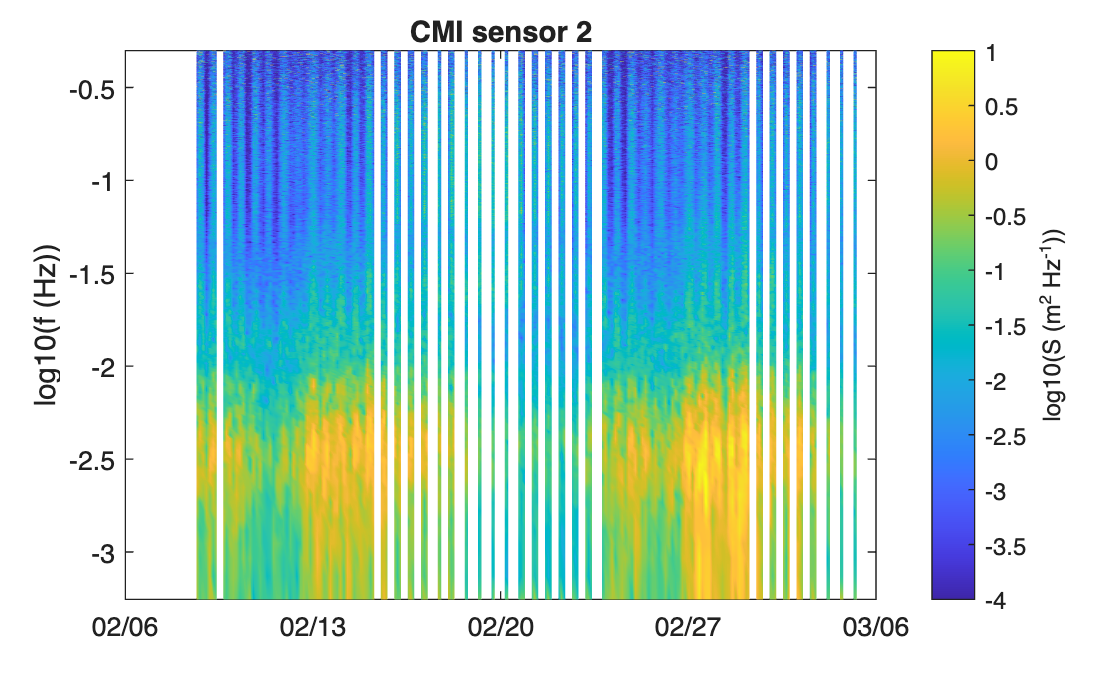

load CMI_data.mat
x = detrend(CMI.p2);
t = CMI.t;
[m,n] = size(x);
navg = 5;
r_win = .1;
tm = mean(t);

[S,Su,Sl,f] = auto_spc(x(:,1),1,navg,r_win);
Nf = length(f);
Sout = NaN(Nf,n);
for j = 1:n
    [S,Su,Sl,f] = auto_spc(x(:,j),1,navg,r_win);
    Sout(:,j) = S;
end

figure (1)
pcolor(tm,log10(f),log10(Sout));
shading interp
ylabel('log10(f (Hz))')
cb = colorbar;
ylabel(cb,'log10(S (m^2 Hz^{-1}))')
caxis([-4 1])
datetick('x')
title('CMI sensor 2')